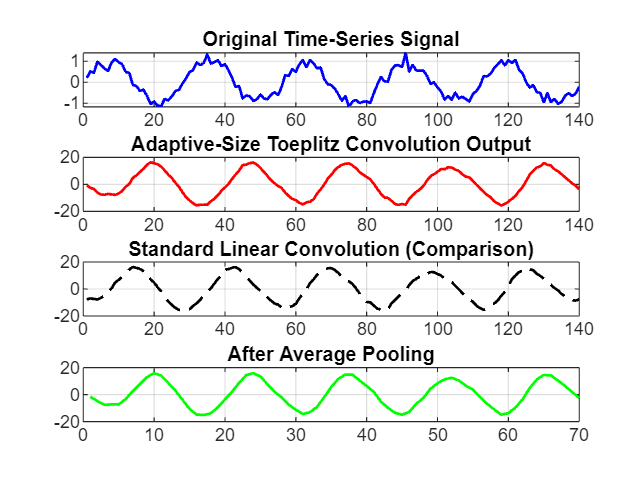

%% Adaptive-Size Adaptive Toeplitz Convolution
% Maths for Computing – Improved Version

clc; clear; close all;

%% ----------------------------------------
% 1. Generate discrete input signal
%% ----------------------------------------
n = 140;
t = linspace(0,1,n);
x = sin(2*pi*5*t) + 0.2*randn(1,n);

%% ----------------------------------------
% 2. Compute signal statistics
%% ----------------------------------------
mu = mean(x);
sigma = std(x);

%% ----------------------------------------
% 3. Robust adaptive kernel size
%% ----------------------------------------
alpha = 2;                 % variation sensitivity
beta  = 0.8;               % length sensitivity

k = 2 * floor(alpha * sigma + beta * log(n)) + 1;
k = max(k,5);              % minimum meaningful size
k = min(k,15);             % keep computation reasonable

%% ----------------------------------------
% 4. Construct adaptive kernel (any size)
%% ----------------------------------------
center = (k+1)/2;
K = zeros(1,k);

for i = 1:k
    K(i) = mu + (i - center)*sigma;
end

%% ----------------------------------------
% 5. Construct Toeplitz matrix
%% ----------------------------------------
first_col = [x(1), zeros(1,k-1)]';
first_row = x;
T = toeplitz(first_col, first_row);   % k × n

%% ----------------------------------------
% 6. Toeplitz convolution (matrix operation)
%% ----------------------------------------
y_toeplitz = K * T;
y_toeplitz = y_toeplitz(1:n);

%% ----------------------------------------
% 7. Standard linear convolution (comparison)
%% ----------------------------------------
y_standard = conv(x, K, 'same');

%% ----------------------------------------
% 8. Average pooling (stride = 2)
%% ----------------------------------------
y_pooled = (y_toeplitz(1:2:end-1) + y_toeplitz(2:2:end)) / 2;

%% ----------------------------------------
% 9. Visualization
%% ----------------------------------------
figure('Color','w');

subplot(4,1,1)
plot(x,'b','LineWidth',1.2)
title('Original Time-Series Signal')
grid on

subplot(4,1,2)
plot(y_toeplitz,'r','LineWidth',1.2)
title('Adaptive-Size Toeplitz Convolution Output')
grid on

subplot(4,1,3)
plot(y_standard,'k--','LineWidth',1.2)
title('Standard Linear Convolution (Comparison)')
grid on

subplot(4,1,4)
plot(y_pooled,'g','LineWidth',1.2)
title('After Average Pooling')
grid on


%% ----------------------------------------
% 10. Display results
%% ----------------------------------------
disp('Adaptive-Size Toeplitz Convolution Results')

Adaptive-Size Toeplitz Convolution Results


disp('-----------------------------------------')

-----------------------------------------


disp(['Signal Length            : ', num2str(n)])

Signal Length            : 140


disp(['Adaptive Kernel Size     : ', num2str(k)])

Adaptive Kernel Size     : 11


disp(['Adaptive Kernel Values   : [', num2str(K), ']'])

Adaptive Kernel Values   : [-3.5271     -2.8223     -2.1175     -1.4128    -0.70799  -0.0032245     0.70155      1.4063      2.1111      2.8159      3.5206]


disp(['Toeplitz Output Length   : ', num2str(length(y_toeplitz))])

Toeplitz Output Length   : 140


disp(['Pooled Output Length     : ', num2str(length(y_pooled))])

Pooled Output Length     : 70


size(K)

ans =      1    11


size(T)

ans =     11   140
